# LSTM

## Load data


XTrain = load(fullfile('DataSet','HyperparameterSearch','Train','XSearchTrain.mat')).XSearchTrain;
YTrain = load(fullfile('DataSet','HyperparameterSearch','Train','YSearchTrain.mat')).YSearchTrain;
XTest = load(fullfile('DataSet','HyperparameterSearch','Test','XSearchTest.mat')).XSearchTest;
YTest = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;

trainDs = {XTrain, YTrain};
testDs = {XTest, YTest};


## Try different 2nd layer

#### just flatten

numFeatures = 3;
numBlocks = 2;
numHiddenUnits = 32;
numResponse = 4;
layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
%                 convolution2dLayer([3 1],numFilter,'Stride',[1 1],'Padding',[1 1 0 0])
        
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

#### fc

layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
%                 convolution2dLayer([3 1],numFilter,'Stride',[1 1],'Padding',[1 1 0 0])
        flattenLayer("Name",'flatten')
        fullyConnectedLayer(32,'Name','fullyconect')
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

#### Cov

layer  = [sequenceInputLayer(numFeatures, 'Normalization','zerocenter','Name','sequenceInputLayer')
        convolution2dLayer([3 1],32,'Stride',[1 1],'Padding',[1 1 0 0])
        flattenLayer("Name",'flatten')        
        ]; % fc
lgraph = layerGraph(layer);
outputName = lgraph.Layers(end).Name;
for i = 1:numBlocks
    layers = [lstmLayer(numHiddenUnits,'OutputMode','sequence','Name',"lstm_"+i)
            layerNormalizationLayer('Name',"layernorm_"+i)];
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"lstm_"+i);
    outputName = "layernorm_"+i;
end
layers = [fullyConnectedLayer(numResponse,'Name','fc')
        softmaxLayer
        classificationLayer];                
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,'fc');

### Train

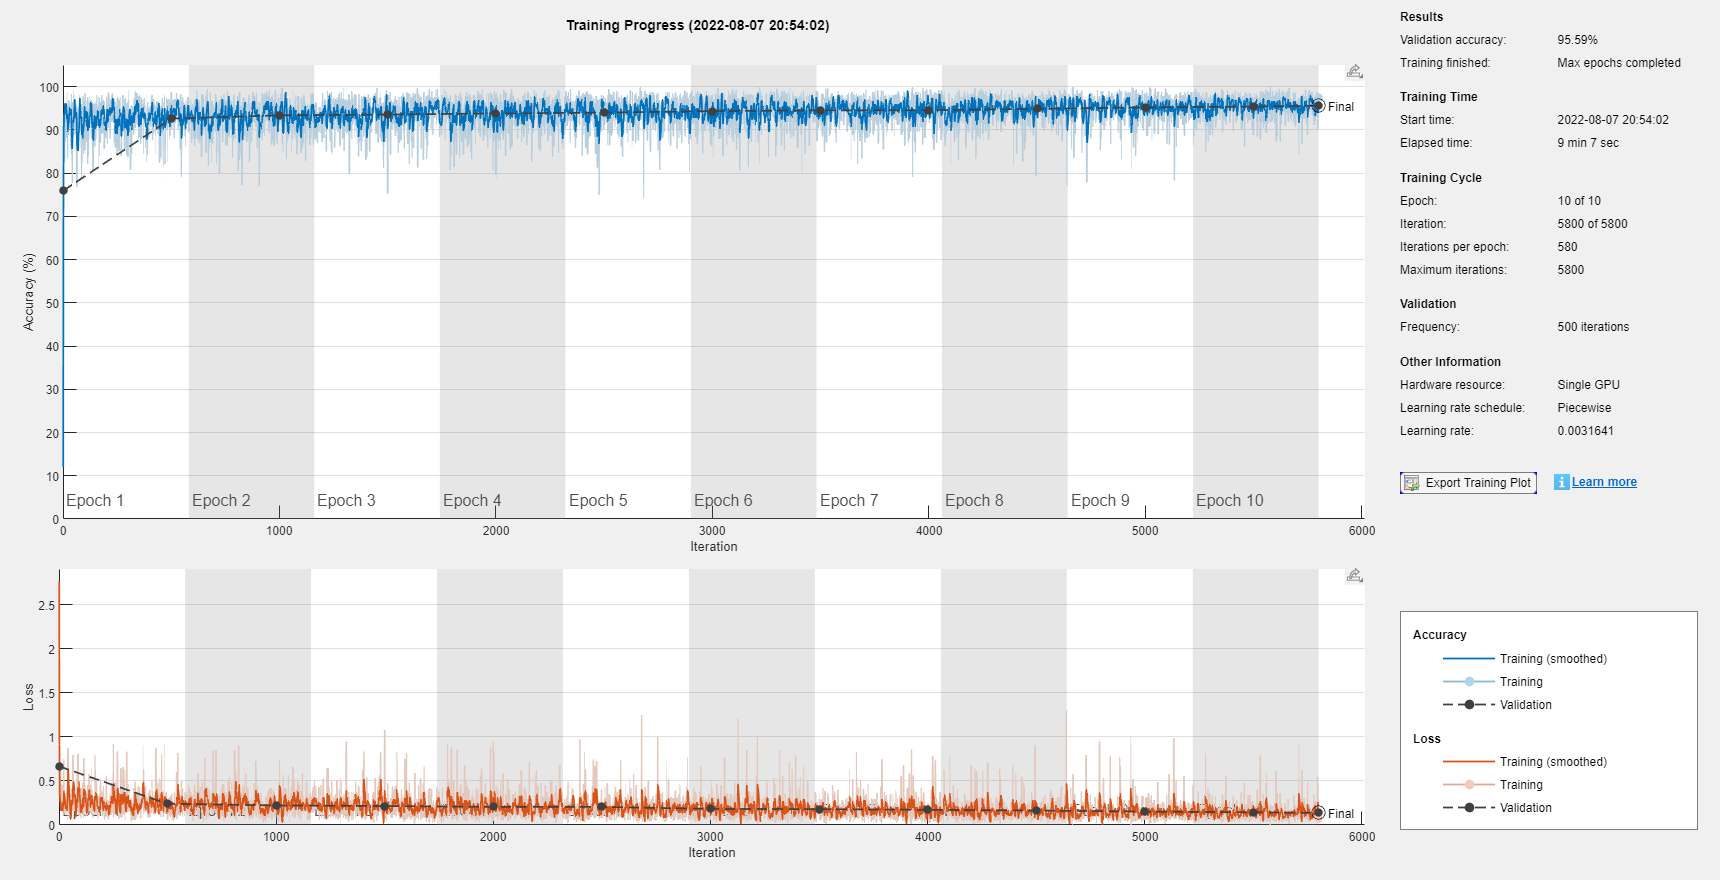

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize',8, ...
    'InitialLearnRate',0.01, ...
    'LearnRateDropPeriod',2, ...
    'LearnRateDropFactor',0.75, ...
    'LearnRateSchedule','piecewise', ...
    'Plots','training-progress',...
    'GradientThreshold',1, ...
    'shuffle','every-epoch',...
    'Verbose',0,...
    'DispatchInBackground',true, ...
    'ValidationData',{XTrain,YTrain}, ...
    'ValidationFrequency',500);
    


net= trainNetwork(XTrain,YTrain,lgraph,options);



YPred = classify(net, XTest, "MiniBatchSize",8);

%%%%%%%%%%%%%%%%%
valError = 0;
for k = 1:length(YPred)
    % fix this
    valError = valError + mean(YPred{k} == YTest{k});
end
% return a numeric scalar
valError = 1 - valError/length(YPred);%
%%%%%%%%%%%%%%%%%%

save('LSTM/lstm.mat',"net",'-mat');%0.0831



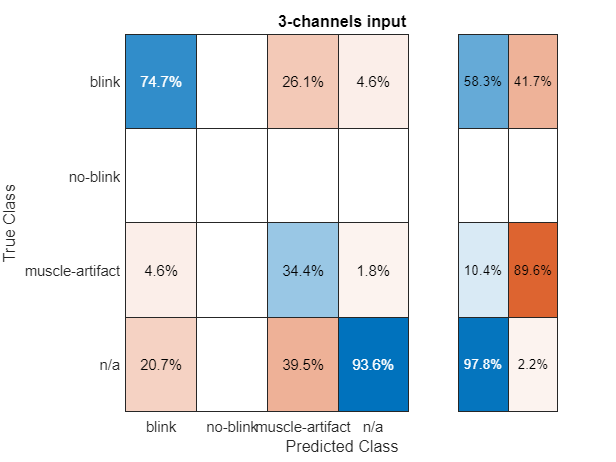



TX = {};
for k = 1:numel(testDs)
    TX{end+1} = testDs{k}{1};
end


TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(testDs{1})
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end

confusionchart(TY(:),Y(:),'Normalization','column-normalized','Title','3-channels input','RowSummary','row-normalized');